assert(endsWith(pwd, "\non-ferromagnetic metal plate with hole in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)
Coil.series_resistance = 0; % (Ohm)

Coil_pos = [-10e-3, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, [1,0,0], deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 1;
Sensor.side_length = 1e-3;

Sensor_pos = [-10e-3, 0, 1.5e-3];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos);
clear Sensor_pos

#### Model

vertex_file  = 'plate-l72-h2_hole-d12_vertex.csv';
element_file = 'plate-l72-h2_hole-d12_element.csv';
Model = BuildModel3D('File', vertex_file, element_file, 1e-3);

build model took 0.35 seconds


clear vertex_file element_file

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 21.63 seconds


#### Solve in time domain

V_E = 1 ; % (V)
pulse_width = 3e-3; % (s)
Coil.time_domain.voltage = @(t) V_E * (t > pulse_width*0.001 & t <= pulse_width*1.001);
Coil.time_domain.time_span = [0, 6e-3]; % (s)
clear V_E pulse_width

% I_E = 1; % (A)
% f = 2000; % (Hz)
% omega = 2*pi*f;
% Coil.time_domain.current      = @(t) I_E * sin(omega * t);
% Coil.time_domain.current_diff = @(t) I_E * omega * cos(omega * t);
% Coil.time_domain.time_span = [0, 5e-4]; % (s)
% clear I_E f omega

[Model, Coil, Sensor] = SolveTimeDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 47.90 seconds


#### Plot result

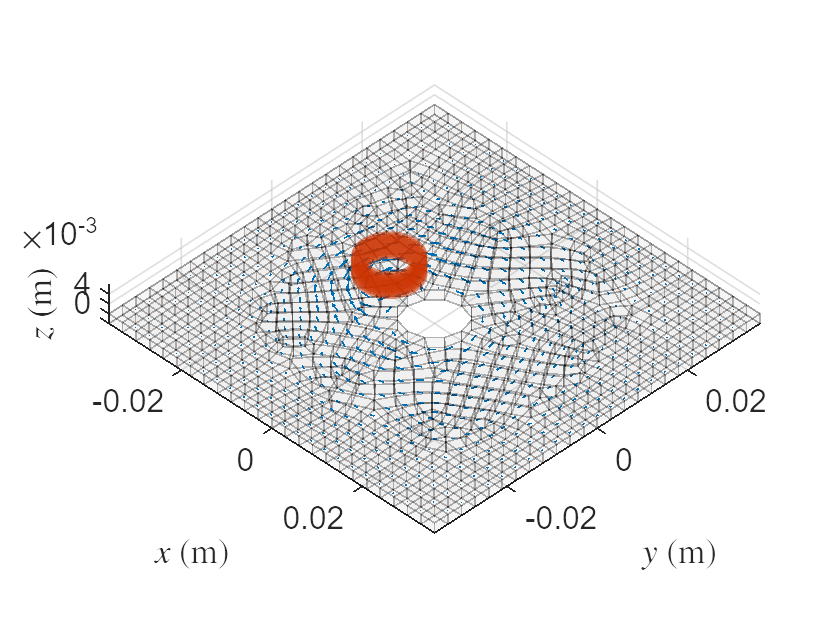

pos = Model.elms_center;
t = 0.4e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
vec = Model.time_domain.J(:,:,k);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear t k pos vec
PlotWorld3D(Model, Coil, Sensor);

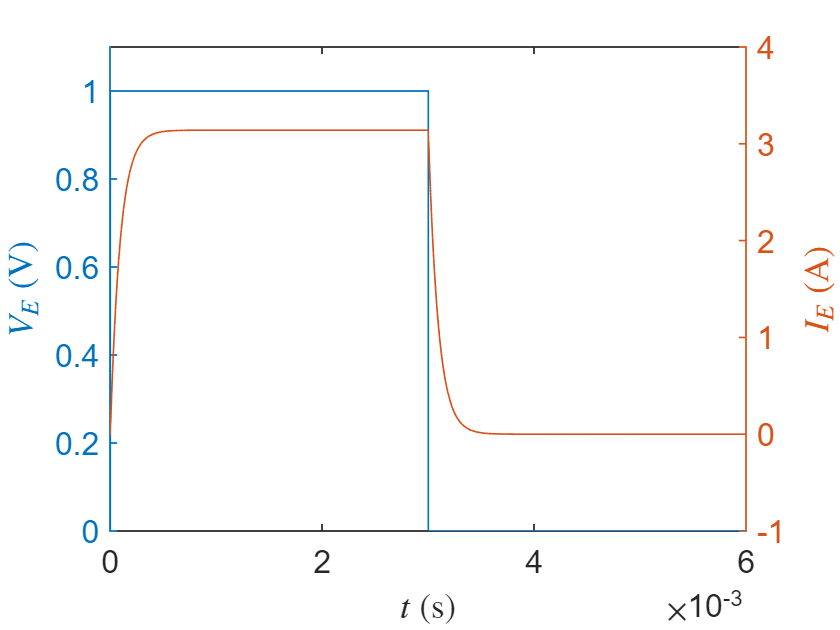

clf


if isfield(Coil.time_domain, 'current')
prefix = 'current_excit';
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I));
xlabel('$t$ (s)', 'Interpreter','latex')
ylabel('$I_E$ (V)', 'Interpreter','latex')
clf
end

if isfield(Coil.time_domain, 'voltage')
prefix = 'voltage_excit';
V = Coil.time_domain.voltage(Sensor.time_domain.t);
yyaxis left
plot(Sensor.time_domain.t, V(:,1))
ylim([-inf, max(V(:,1))*1.1])
ylabel('$V_E$ (V)', 'Interpreter','latex')
yyaxis right
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I(1,1,:)));
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')
clf
clear V
end

## Compare with FEA

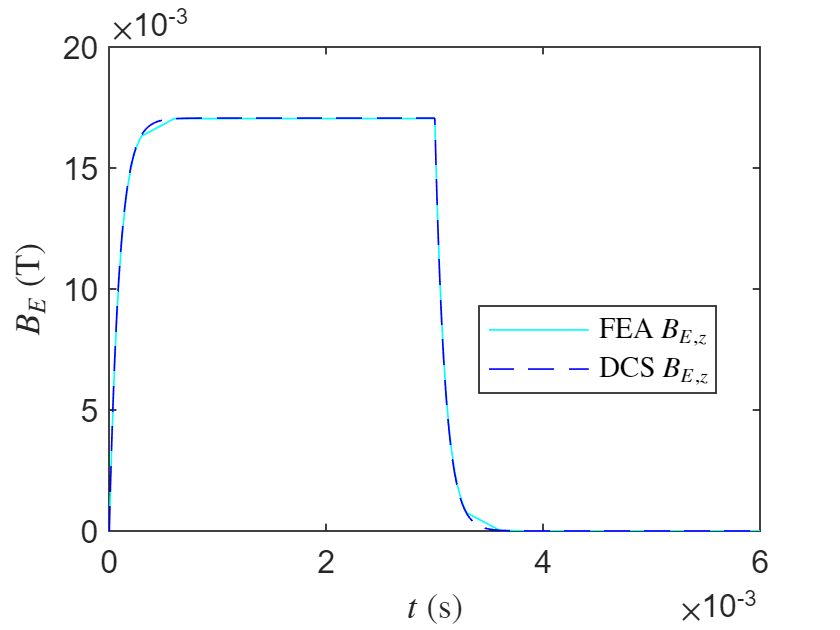

data = readmatrix(sprintf("FEA_data/%s_B_E.csv",prefix), 'CommentStyle','%');
data = reshape(data(4:end), 4, []);
FEA.t     = data(1,:);
FEA.B_E_x = data(2,:);
FEA.B_E_y = data(3,:);
FEA.B_E_z = data(4,:);
data = readmatrix(sprintf("FEA_data/%s_B.csv",prefix), 'CommentStyle','%');
data = reshape(data(4:end), 4, []);
FEA.B_C_x = data(2,:) - FEA.B_E_x;
FEA.B_C_y = data(3,:) - FEA.B_E_y;
FEA.B_C_z = data(4,:) - FEA.B_E_z;


plot(FEA.t, FEA.B_E_z, 'c-', 'DisplayName','FEA $B_{E,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(3,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

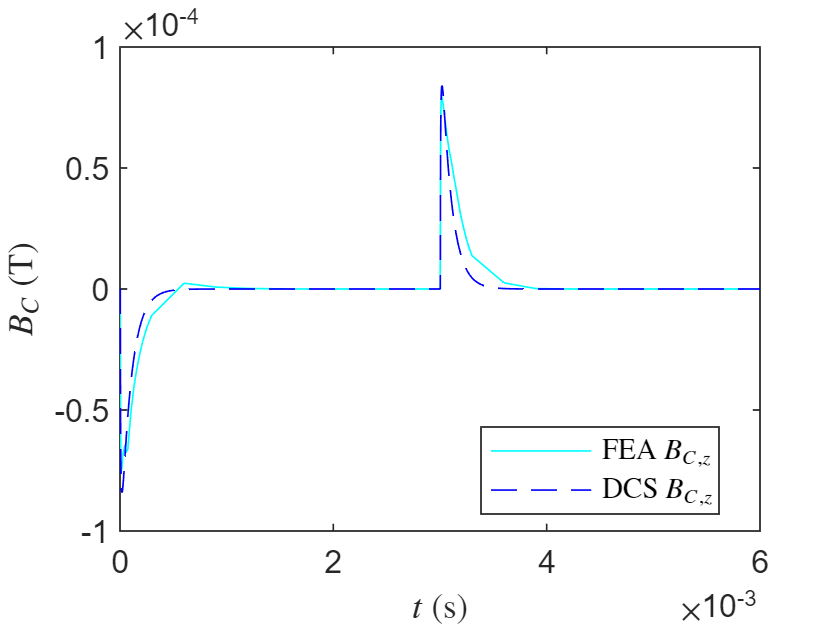

clf

plot(FEA.t, FEA.B_C_z, 'c-', 'DisplayName','FEA $B_{C,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(3,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

clear data